% % MILP problem to risk appetite model
clc
clear all

% % Loading data set
IS = xlsread("Utility_estimation.xlsx",'IS_SU'); % Information System from respondent evaluations
Data_based_case = xlsread('Utility_estimation.xlsx','DT_SU'); % Utility estimation from RSGA


% % Define the features
U = Data_based_case(:,1); % Number of observation
Utility_R = round(Data_based_case(:,1:end-1)); % Number of utility estimation

Cond_R = IS(:,1:end-1); % Number of conditional seaport risk factors

Dec_R = Data_based_case(:,end); % Decisional seaport risk factor


% % Formulating the problem
utilityprob = optimproblem("ObjectiveSense","minimize")

utilityprob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [0×0 struct] containing 0 OptimizationVariables
         Objective: [0×0 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  No problem defined.


e = optimvar('e',71,61,'Type','integer','LowerBound',0,'UpperBound',1);
show(e)

    [ e(1, 1)     e(1, 2)     e(1, 3)     e(1, 4)     e(1, 5)     e(1, 6)     e(1, 7)     e(1, 8)     e(1, 9)     e(1, 10)     e(1, 11)     e(1, 12)     e(1, 13)     e(1, 14)     e(1, 15)     e(1, 16)     e(1, 17)     e(1, 18)     e(1, 19)     e(1, 20)     e(1, 21)     e(1, 22)     e(1, 23)     e(1, 24)     e(1, 25)     e(1, 26)     e(1, 27)     e(1, 28)     e(1, 29)     e(1, 30)     e(1, 31)     e(1, 32)     e(1, 33)     e(1, 34)     e(1, 35)     e(1, 36)     e(1, 37)     e(1, 38)     e(1, 39)     e(1, 40)     e(1, 41)     e(1, 42)     e(1, 43)     e(1, 44)     e(1, 45)     e(1, 46)     e(1, 47)     e(1, 48)     e(1, 49)     e(1, 50)     e(1, 51)     e(1, 52)     e(1, 53)     e(1, 54)     e(1, 55)     e(1, 56)     e(1, 57)     e(1, 58)     e(1, 59)     e(1, 60)     e(1, 61)  ]
    [ e(2, 1)     e(2, 2)     e(2, 3)     e(2, 4)     e(2, 5)     e(2, 6)     e(2, 7)     e(2, 8)     e(2, 9)     e(2, 10)     e(2, 11)     e(2, 12)     e(2, 13)     e(2, 14)     e(2, 15)     e(2, 16)     e(2, 1


utilityEstimation = Utility_R;
riskPreferences = Cond_R;
Decisional_SR = Dec_R;
Percentage_utility = Utility_R.*Decisional_SR

Percentage_utility =   -298  -298   -86    82    46   194   208    58    94   -32  -204    68    68  -204   110   194   236   100   134  -154  -350    36   236   114  -350  -160    82   112   -90  -178     4   102   126    24  -180  -180   160   176   -78   188  -268  -268   336    88  -216   424  -210   184   224  -408
   225  -354   240  -111   -18  -378   312    36    45  -426   531  -450  -174   444    45    27   126  -378   -93   576   357  -378  -402   -63   255  -534   372   420    87  -534   438  -255     3   342   126   312  -534  -249  -168    48   270   330  -378  -102  -207   195    12   300  -153  -147
   -80    -6   170  -226   148   -42   216    32  -212   358  -208   102   180  -208   -18  -208   210   -38  -376   100   278    10  -354   -26   196   178  -292    42   290    32  -312    16    46  -118   118    98   -22   -74  -186  -176   418  -186  -186   316     4    -2    -2  -320   160   160
    84  -162  -158   -12    74   204   142   -42  -128     6  -268   -28    

Freq_entities = length(Utility_R)/3

Freq_entities = 23.6667

F = 1./Freq_entities

F = 0.0423

predprob = utilityEstimation/sum(utilityEstimation(:));

% % Creating expressions
Z = F.*sum(sum(Cond_R.*predprob.*utilityEstimation.*e))

Z =   Linear OptimizationExpression

    55.18061*e(1, 1) + 69.90472*e(2, 1) + 11.93041*e(3, 1) + 21.92212*e(4, 1) + 65.74151*e(5, 1) + 0.7456504*e(6, 1) + 229.8592*e(7, 1) + 59.16736*e(8, 1) + 45.97183*e(9, 1) + 8.356255*e(10, 1) + 80.53024*e(11, 1) + 1.677713*e(12, 1) + 60.39768*e(13, 1) + 21.00249*e(14, 1) + 23.66694*e(15, 1) + 2.691798*e(16, 1) + 33.4449*e(17, 1) + 0.2435791*e(18, 1) + 27.92709*e(19, 1) + 188.0157*e(20, 1) + 27.92709*e(21, 1) + 60.48716*e(22, 1) + 155.8906*e(23, 1) + 17.89561*e(24, 1) + 3.589064*e(25, 1) + 2.15493*e(26, 1) + 10.82684*e(27, 1) + 38.21707*e(28, 1) + 2.545153*e(29, 1) + 0.007456504*e(30, 1) + 12.88484*e(31, 1) + 99.42005*e(32, 1) + 1.677713*e(33, 1) + 240.1118*e(34, 1) + 38.21707*e(35, 1) + 0.6039768*e(36, 1) + 4.660315*e(37, 1) + 73.68268*e(38, 1) + 31.73737*e(39, 1) + 161.5079*e(40, 1) + 0.08947804*e(41, 1) + 25.85915*e(42, 1) + 13.78708*e(43, 1) + 89.726

utilityprob.Objective = Z; % Objective function
show(Z)


  55.18061*e(1, 1) + 69.90472*e(2, 1)
+ 11.93041*e(3, 1) + 21.92212*e(4, 1)
+ 65.74151*e(5, 1) + 0.7456504*e(6, 1)
+ 229.8592*e(7, 1) + 59.16736*e(8, 1)
+ 45.97183*e(9, 1) + 8.356255*e(10, 1)
+ 80.53024*e(11, 1) + 1.677713*e(12, 1)
+ 60.39768*e(13, 1) + 21.00249*e(14, 1)
+ 23.66694*e(15, 1) + 2.691798*e(16, 1)
+ 33.4449*e(17, 1) + 0.2435791*e(18, 1)
+ 27.92709*e(19, 1) + 188.0157*e(20, 1)
+ 27.92709*e(21, 1) + 60.48716*e(22, 1)
+ 155.8906*e(23, 1) + 17.89561*e(24, 1)
+ 3.589064*e(25, 1) + 2.15493*e(26, 1)
+ 10.82684*e(27, 1) + 38.21707*e(28, 1)
+ 2.545153*e(29, 1) + 0.007456504*e(30, 1)
+ 12.88484*e(31, 1) + 99.42005*e(32, 1)
+ 1.677713*e(33, 1) + 240.1118*e(34, 1)
+ 38.21707*e(35, 1) + 0.6039768*e(36, 1)
+ 4.660315*e(37, 1) + 73.68268*e(38, 1)
+ 31.73737*e(39, 1) + 161.5079*e(40, 1)
+ 0.08947804*e(41, 1) + 25.85915*e(42, 1)
+ 13.78708*e(43, 1) + 89.72659*e(44, 1)
+ 31.02403*e(45, 1) + 60.89478*e(46, 1)
+ 48.71582*e(47, 1) + 7.247722*e(48, 1)
+ 84.14913*e(49, 1) + 31.17813*e(50, 1)
+ 

% % Defining constaints
for m = 1:71
    for n = 1:61
        if utilityEstimation(m,n) ~= utilityEstimation(n)
            d_ikj(m,n) = 1;
        else
            d_ikj(m,n) = 0;
        end
    end
end

d_ikj_cons1 = sum(d_ikj.*e) <= 1

d_ikj_cons1 =   1×61 Linear OptimizationInequality array with properties:

    IndexNames: {{}  {}}
     Variables: [1×1 struct] containing 1 OptimizationVariable

  See inequality formulation with show.


utilityprob.Constraints.d_ikj_cons1 = d_ikj_cons1

utilityprob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 1 OptimizationConstraint

  See problem formulation with show.


% % Solve the problem
[sol, fval] = solve(utilityprob)

Solving problem using intlinprog.
LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the
optimal value, options.AbsoluteGapTolerance = 0
(the default value). The intcon variables are
integer within tolerance,
options.IntegerTolerance = 1e-05 (the default
value).



sol = struct with fields:
    e: [71×61 double]


fval = 0

sol.e

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

fval

fval = 0

% % Plotting result
h = heatmap(sol.e)

h =   HeatmapChart with properties:

        XData: {61×1 cell}
        YData: {71×1 cell}
    ColorData: [71×61 double]

  Show all properties


h.Title = 'Risk appetite of seaport-user under Scenario II'

h =   HeatmapChart (Risk appetite of seaport-user under Scenario II) with properties:

        XData: {61×1 cell}
        YData: {71×1 cell}
    ColorData: [71×61 double]

  Show all properties


h.XLabel = 'Conditional seaport risk factors'

h =   HeatmapChart (Risk appetite of seaport-user under Scenario II) with properties:

        XData: {61×1 cell}
        YData: {71×1 cell}
    ColorData: [71×61 double]

  Show all properties


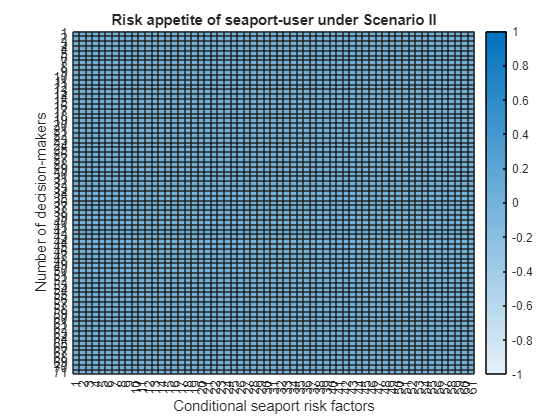

h =   HeatmapChart (Risk appetite of seaport-user under Scenario II) with properties:

        XData: {61×1 cell}
        YData: {71×1 cell}
    ColorData: [71×61 double]

  Show all properties


h.YLabel = 'Number of decision-makers'


s = surf(sol.e)

s =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61]
           YData: [71×1 double]
           ZData: [71×61 double]
           CData: [71×61 double]

  Show all properties


s.EdgeColor = "interp"

s =   Surface with properties:

       EdgeColor: 'interp'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61]
           YData: [71×1 double]
           ZData: [71×61 double]
           CData: [71×61 double]

  Show all properties


s.FaceColor = "interp"

s =   Surface with properties:

       EdgeColor: 'interp'
       LineStyle: '-'
       FaceColor: 'interp'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61]
           YData: [71×1 double]
           ZData: [71×61 double]
           CData: [71×61 double]

  Show all properties


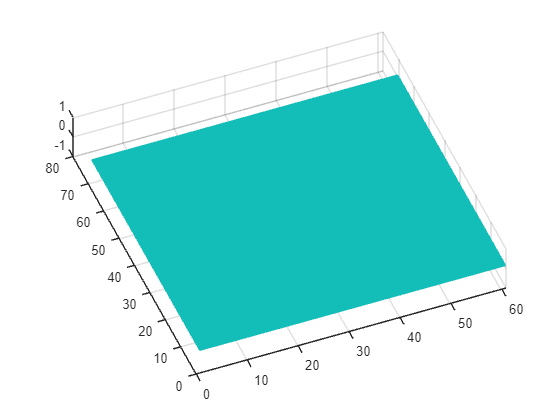

view([-21.627 80.462])